clc;clear all;close all;
%step(GCL,40);hold on
z0=rand(2,1)

z0 =     0.1493
    0.2575



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


zopt =   383.5143
  129.5712


Jopt = 49.1230

x0 =      0
     0


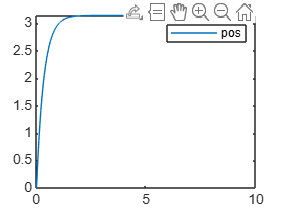

for i=4:4
    [zopt,Jopt]=fmincon(@(z)costo(z,i),z0,[],[],[],[],[],[],@restr)
    x0=[0;0]
    [T,X]=ode45(@(t,x)pend(t,x,control(t,x,zopt)),[0 10],x0);
    plot(T,X(:,1));legend('pos')
end

function J=costo(z,i)
    fun=@(t,x)pend(t,x,control(t,x,z));
    Ts=0.01;
    T=(0:Ts:4)';Y=[];xk=[0;0];
    U=[];
    for k=1:length(T);
        U=[U;control(k*Ts,xk,z)];
        k1=fun(k*Ts,xk);
        k2=fun(k*Ts+Ts/2,xk+k1*Ts/2);
        k3=fun(k*Ts+Ts/2,xk+k2*Ts/2);
        k4=fun(k*Ts+Ts,xk+k3*Ts);
        xk=xk+Ts*(k1+2*k2+2*k3+k4)/6;
        Y=[Y;[1 0]*xk];
    end
    Yref=pi;
    if(i==1)
        J=sum(abs(Y-Yref))+0.01*sum((U.^2).*T);
    elseif(i==2)
        J=sum(abs(Y-Yref).*T)+0.01*sum((U.^2).*T);
    elseif(i==3)
        J=sum((Y-Yref).^2)+0.01*sum((U.^2).*T);
    elseif(i==4)
        J=sum(((Y-Yref).^2).*T)+0.01*sum((U.^2).*T);
    end
end

function [c,c_eq]=restr(z)
    c=[];
    c_eq=[];
end
function u=control(t,x,z)
    K=[z(1) z(2)];
    u=-K*(x-[pi;0]);
end

function dx=pend(t,x,u)
    dx=[x(2);-sin(x(1))-x(2)+u];
end